## Drop Down List Manager

This widget provides the user to edit and select from a list of names, and it does so within a compact space. You can easily add, remove, or rename items from the dropdown control using the connected buttons.

*This widget was designed for R2023b and later.*

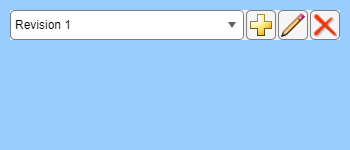

ddlWidget =   DropDownListManager with properties:

              Index: 2
              Value: "Revision 1"
              Items: ["Initial Configuration"    "Revision 1"    "Revision 2"]
          ItemsData: [1×0 double]
        AllowRemove: on
        AllowRename: on
    AllowItemRemove: [0 1 1]
    AllowItemRename: [0 1 1]
        NewItemName: "<New Item>"
       IsAddingItem: 0
     IsRenamingItem: 0
    ItemsChangedFcn: @(src,evt)disp(evt)
           Position: [11 111 330 30]

  Show all properties


% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 350 150]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);
gridObj.RowHeight = {30};

% Create the widget
ddlWidget = wt.DropDownListManager(gridObj);

% The remove and rename buttons are enabled by default as below,
% but you could set them false if you did not want them
ddlWidget.AllowRemove = true;
ddlWidget.AllowRename = true;

% Disable removing or renaming the first list item
ddlWidget.AllowItemRemove(1) = false;
ddlWidget.AllowItemRename(1) = false;

% When you press the "add" button, this is the initial name for the new item
ddlWidget.NewItemName = "<New Item>";

% Assign a callback
ddlWidget.ItemsChangedFcn = @(src,evt)disp(evt);

% Set initial list items
ddlWidget.Items = [
    "Initial Configuration"
    "Revision 1"
    "Revision 2"
    ];

% Set the initial selection
ddlWidget.Value = "Revision 1"

## Numeric Array

This widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

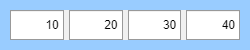

naWidget =   NumericArray with properties:

                  Value: [10 20 30 40]
                 Limits: [0 1000]
    LowerLimitInclusive: on
    UpperLimitInclusive: on
            Restriction: increasing
            Orientation: horizontal
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [11 11 230 30]

  Show all properties


% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
naWidget = wt.NumericArray(gridObj);

% Configure the widget
naWidget.Tooltip = "Enter the increasing point values between 0 and 1000.";

% Optional limits and restrictions
naWidget.Limits = [0, 1000];
naWidget.LowerLimitInclusive = true;
naWidget.UpperLimitInclusive = true;
naWidget.Restriction = "increasing";

% Assign a callback
naWidget.ValueChangedFcn = @(src,evt)disp(evt);

% Set initial values
naWidget.Value = [10 20 30 40]

## Range Field

This widget combines multiple numeric edit fields that form elements of a 1-dimensional array. It is intended for small arrays typically 2 to 5 values. Optionally you may impose restrictions on the numerical range. You can also force the array to be `increasing` or `decreasing`. You can also set orientation as `horizontal` or `vertical`.

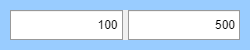

rfWidget =   RangeField with properties:

                  Value: [100 500]
                 Limits: [0 Inf]
    LowerLimitInclusive: off
    UpperLimitInclusive: on
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [11 11 230 30]

  Show all properties


% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 50]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
rfWidget = wt.RangeField(gridObj);

% Configure the widget
rfWidget.Tooltip = "Enter the range of positive values to use (must be > 0).";

% Optional limits
rfWidget.Limits = [0, inf];
rfWidget.LowerLimitInclusive = false;
rfWidget.UpperLimitInclusive = true;

% Assign a callback
rfWidget.ValueChangedFcn = @(src,evt)disp(evt);

% Set initial values
rfWidget.Value = [100 500]

## Row Entries Table

This widget is intended to enable display and editing of simple lists when each item (row) has multiple attributes (columns) to configure. You can add or remove rows using the buttons. You may optionally enable ordering buttons to move items up and down the list.

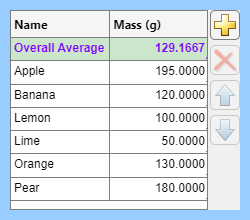

rtWidget =   RowEntriesTable with properties:

                   Data: [7×2 table]
           NewRowFormat: {["New Fruit"]  [0]}
              Orderable: on
        AllowItemRemove: [0 1 1 1 1 1 1]
      AllowItemOrdering: [0 1 1 1 1 1 1]
    StyleConfigurations: [1×3 table]
             TableWidth: '1x'
            TableHeight: '1x'
        ValueChangedFcn: @(src,evt)disp(evt)
               Position: [100 100 100 100]

  Show all properties


% Create a figure with a grid layout
figObj = uifigure("Position",[100 100 250 220]);
gridObj = uigridlayout(figObj,[1 1],"BackgroundColor",[.6 .8 1]);

% Create the widget
rtWidget = wt.RowEntriesTable(gridObj);

% Configure the widget
rtWidget.Tooltip = "Specify the available fruit and average mass of each.";
rtWidget.Orderable = true; % Enables the up/down buttons to reorder items

% Prepare a data table
fruitData = cell2table({
    "Apple", 195
    "Banana", 120
    "Lemon", 100
    "Lime", 50
    "Orange", 130
    "Pear", 180
    }, "VariableNames", ["Name","Mass (g)"]);

% Add a top row showing the mean
meanMass = mean(fruitData.("Mass (g)"));
fruitData = [
    {"Overall Average", meanMass}
    fruitData
    ];

% When the user pushes "add", insert this row
rtWidget.NewRowFormat = {"New Fruit",0};

% Assign a callback
rtWidget.ValueChangedFcn = @(src,evt)disp(evt);

% Fix the top row to stay in place and style it
rtWidget.AllowItemRemove(1) = false;
rtWidget.AllowItemOrdering(1) = false;
firstRowStyle = uistyle("BackgroundColor",[.8 .9 .8],"FontWeight","bold","FontColor",[.5 0 1]);
rtWidget.addStyle(firstRowStyle, "row", 1)

% Pause for a moment to ensure the widget renders correctly in this
% example. (You can omit this in your code.)
pause(1)

% Attach data
rtWidget.Data = fruitData